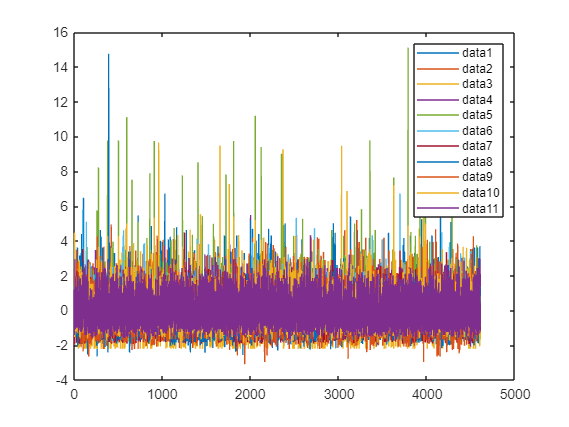

clc;
%clear all;
close all;
data = readtable('winequality-dataset_final_matlab.csv');

data = table2array(data);
features = normalize(data(:,1:11));
target = data(:,12);
normalized_data = [features,target];

plot(features);
legend();

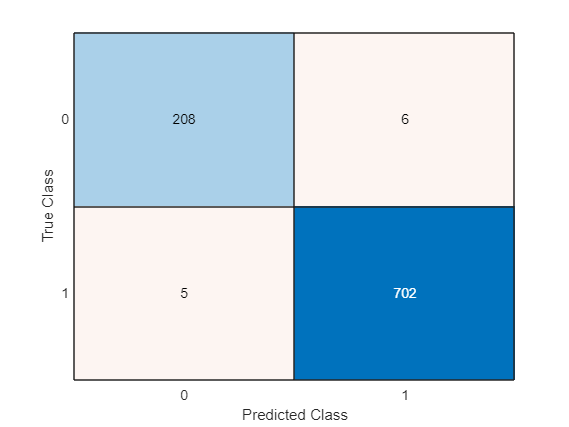


target_vec = [];
for i = 1:size(target,1)
    if(target(i) == 1)
        target_vec = [target_vec;[1,0]];
    else
        target_vec = [target_vec;[0,1]];
    end
end

[m,n] = size(data);
train_data = normalized_data(1:ceil(0.8*m),:);
test_data = normalized_data(ceil(0.8*m)+1:end,:);

[trainedClassifier, validationAccuracy] = LinearDiscPCA(train_data);
[testClassifier, test_validationAccuracy] =LinearDiscrTest(test_data);

trainedmodel =  LinearDiscrTest(train_data);
predictions = trainedmodel.predictFcn(test_data(:,1:11));
confusionchart(test_data(:,12),predictions);

ConfusionMat= confusionmat(test_data(:,12),predictions);
disp(ConfusionMat);

   208     6
     5   702




acc = sum(diag(ConfusionMat))/sum(sum(ConfusionMat));
disp(acc);

    0.9881

